clc;
clear;
close all;

load('modelo_lin.mat')

# Tarea1:

## Modelo Longitudinal:

%Carga del modelo
Along = longmod.A;
Blong = longmod.B;
Clong = longmod.C;
Dlong = longmod.D;

%eliminacion de datos irrelevantes
Along(abs(Along)<1e-10)=0;
Blong(abs(Blong)<1e-10)=0;
Clong(abs(Clong)<1e-10)=0;
Dlong(abs(Dlong)<1e-10)=0;

longNames = longmod.StateName;
Blong=Blong(:,1);
Clong=Clong(4,:);
Dlong=Dlong(4,1);

G=ss(Along,Blong,Clong,Dlong)

G =
 
  A = 
               x1          x2          x3          x4          x5          x6
   x1     -0.5961      0.8011      -0.871      -9.791   5.053e-05     0.01263
   x2     -0.7454      -7.581       15.72     -0.5272  -0.0009384           0
   x3       1.042      -7.427      -15.85           0           0    -0.01318
   x4           0           0           1           0           0           0
   x5    -0.05377      0.9986           0         -17           0           0
   x6       135.8       7.315           0           0    -0.08268      -5.919
 
  B = 
           u1
   x1  0.4681
   x2  -2.711
   x3  -134.1
   x4       0
   x5       0
   x6       0
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   0   0   0   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.




s=tf('s');

wB1=8*2*pi;
A1=0.0003;
M1=0.3;

wB3=6*2*pi;
A3=0.1;
M3=1;

% W1=(0.5*s+0.015)/(s+0.00015);
hold on
W1=(s/M1+wB1)/(s+wB1*A1);
% bodemag(1/W1,'r');
W2=tf(1,1)  

W2 =
 
  1
 
Static gain.



% bodemag(1/W2,'g');
W3=(1+s/M3)/(1+(s/(wB3*A3)));
% bodemag(1/W3,'b');
hold off

% sym k;
% k.u='e';
% k.y='u';
% G.u='u';
% G.y='y';
% W2.u='u';
% W2.y='z2';
% W3.u='s';
% W3.y='z3';
% W1.u='e';
% W1.y='z3';
% sum1=sumblk('e=r-y');
% sum2=sumblk('s=y+d0');
% 
% Gg=connect(k,G,W2,W3,W1,sum1,sum2,'r','d0','z1','z2','z3')


[K,CL,gamma]=mixsyn(G,W1,W2,W3)

K =
 
  A = 
               x1          x2          x3          x4          x5          x6          x7          x8
   x1    -0.01508           0           0           0           0           0           0           0
   x2   4.065e-13       -3.77   4.806e-18   5.583e-16   -5.86e-15           4   5.404e-20   1.032e-18
   x3      -180.8       23.14     -0.5944      0.5294       1.838       116.3   2.687e-05     0.01213
   x4        1047        -134     -0.7551      -6.007     0.02437      -730.9  -0.0008014    0.002903
   x5   5.177e+04       -6627      0.5623       70.39      -791.9  -3.612e+04    0.006778      0.1304
   x6    4.84e-13  -6.228e-14   5.723e-18   6.648e-16           1  -3.374e-13   6.435e-20   1.229e-18
   x7  -3.331e-10   4.286e-11    -0.05377      0.9986   4.802e-12         -17  -4.429e-17  -8.457e-16
   x8  -1.794e-10   2.309e-11       135.8       7.315   2.586e-12   1.251e-10    -0.08268      -5.919
 
  B = 
               u1
   x1           8
   x2  -4.366e-15
   x3 

gamma = 5.3206


OL=series(K,G)

OL =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8          x9         x10
   x1      -0.5961      0.8011      -0.871      -9.791   5.053e-05     0.01263      -180.8       23.14    0.001674     -0.2717
   x2      -0.7454      -7.581       15.72     -0.5272  -0.0009384           0        1047        -134   -0.009694       1.573
   x3        1.042      -7.427      -15.85           0           0    -0.01318   5.177e+04       -6627     -0.4794       77.81
   x4            0           0           1           0           0           0           0           0           0           0
   x5     -0.05377      0.9986           0         -17           0           0           0           0           0           0
   x6        135.8       7.315           0           0    -0.08268      -5.919           0           0           0           0
   x7            0           0           0           0           0           0    -0.01508       

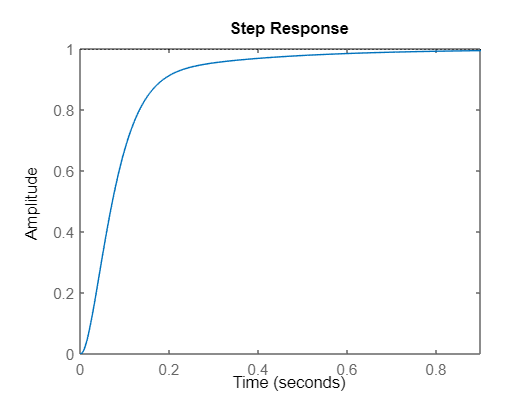

GCL=feedback(OL,1);
figure (1)
step(GCL)

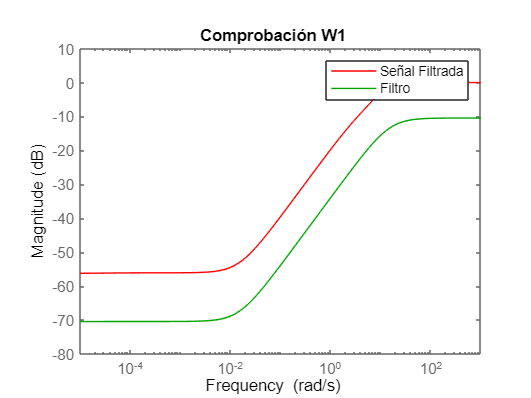


%Comprobación W1
S = feedback(1,OL);
figure (2)
bodemag(S,'r');
hold on
bodemag(1/W1,'g');title("Comprobación W1");
hold off
legend("Señal Filtrada", "Filtro");

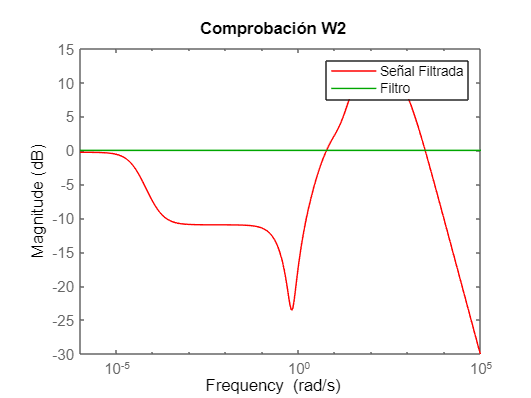

%%Comprobación W2
S = feedback(1,OL);
figure(3)
bodemag(S*K,'r');
hold on
bodemag(1/W2,'g'), title("Comprobación W2");
legend("Señal Filtrada", "Filtro");
hold off

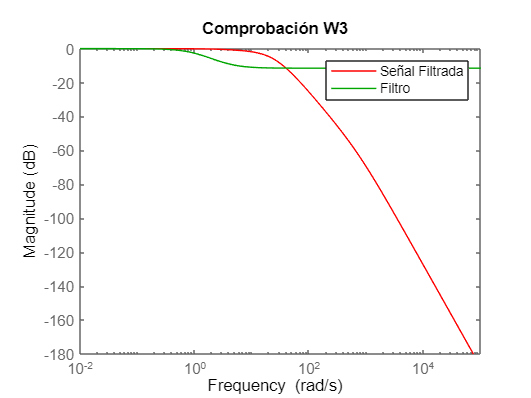

%% Comprobacion W3

T = feedback(OL,1);
figure (4)
bodemag(T,'r');
hold on
bodemag(1/W3,'g'), title("Comprobación W3");
legend("Señal Filtrada", "Filtro");
hold off

figure()
plot(out.ScopeData.time,out.ScopeData.signals.values)
title('H_{inf} con ruido y perturbación')
legend({'\theta','q'})

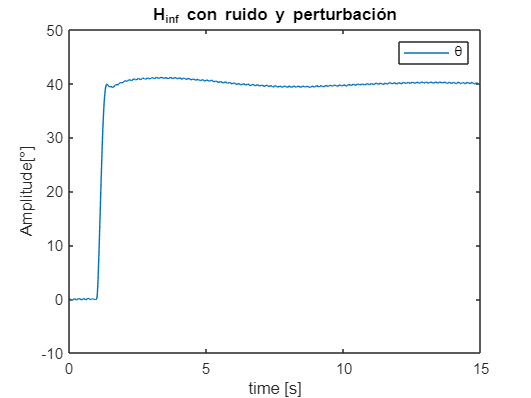

xlabel('time [s]') 
ylabel('Amplitude[°]') 